%Define network
net = network.IEEE9bus_;

%コントローラAGC
con_agc = controller.broadcast_PI_AGC(net,1:3,1:3,-100,-500);
net.add_controller_global(con_agc);

%コントローラレトロフィット
Q = [1, 1e8, 1, 0, 0, 0, 0];           
R  = [1e-5, 1e8];

for i = []
    con = controller.local_LQR(net,i,diag(Q),diag(R));
    net.add_controller_local(con);
end


%地絡応答でテスト
time = [0, 10];
fault = {{[1,1.05],1}};
out = net.simulate(time,'fault',fault);


 Simulation Start !!
 
0s                                                                                                10s
|        10%       20%       30%       40%       50%       60%       70%       80%       90%        |
|---------o---------o---------o---------o---------o---------o---------o---------o---------o---------|
|>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>|


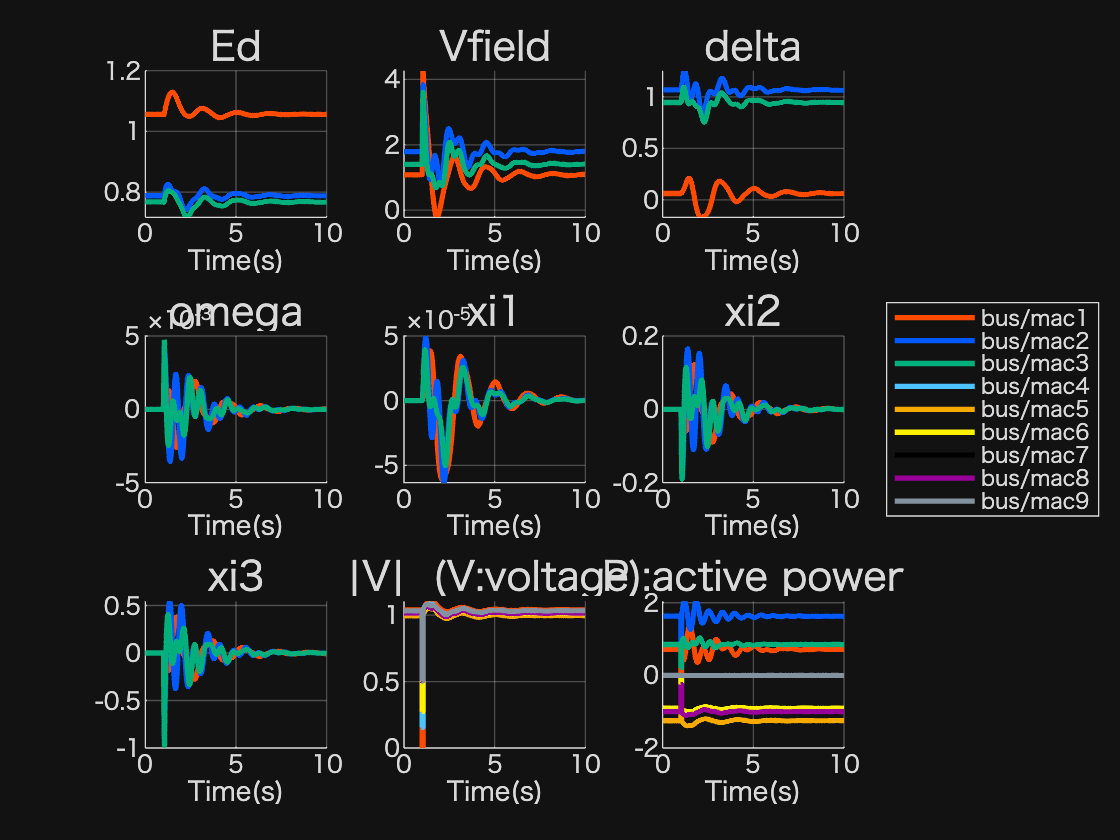

out.plot